# Disk-on-a-Pipe Simulator

### By: Arnaldo Rodriguez-Gonzalez

- This MATLAB Live Script is intended to give you a physical sense of what the motion of a disk of mass $m=1$kg and radius $r = 1$meter is while rolling or sliding inside of another disk of radius $R = 4$ meters under the influence of gravity.

- Select whether you would like to observe rolling without slip or pure slipping by selecting the appropriate option in the dropdown menu, and then press the button to run the simulation!

- The animation uses a real-time computer clock, so the animation might be laggy if your computer is slow.

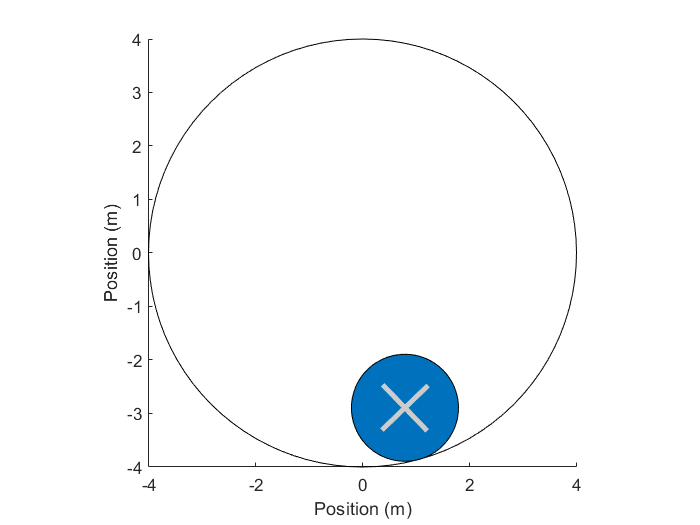

clear
close all
theta = -64;
rollorslip = 0;
 
if rollorslip == 0
    [t,y] = ode45(@(t,y)rollingball(t,y),linspace(0,31,10000),[deg2rad(theta),3*deg2rad(theta),0,0]);
elseif rollorslip == 1
    [t,y] = ode45(@(t,y)slidingball(t,y),linspace(0,31,10000),[deg2rad(theta),3*deg2rad(theta),0,0]);
end
xg = 3*sin(y(:,1));
yg = -3*cos(y(:,1));
xp = xg - 0.6*sin(y(:,2));
yp = yg - 0.6*cos(y(:,2));
xq = xg + 0.6*sin(y(:,2));
yq = yg + 0.6*cos(y(:,2));
xr = xg + 0.6*cos(y(:,2));
yr = yg - 0.6*sin(y(:,2));
xs = xg - 0.6*cos(y(:,2));
ys = yg + 0.6*sin(y(:,2));
a1 = rectangle('Position',[xg(1)-1 yg(1)-1 2 2],'Curvature',[1 1],'FaceColor',[0, 0.4470, 0.7410]);
b1 = rectangle('Position',[-4 -4 8 8],'Curvature',[1 1]);
c1 = line([xp(1) xq(1)],[yp(1) yq(1)],'Color',[0.8 0.8 0.8],'LineWidth',3);
d1 = line([xr(1) xs(1)],[yr(1) ys(1)],'Color',[0.8 0.8 0.8],'LineWidth',3);
axis equal
axis([-4 4 -4 4])
xlabel('Position (m)')
ylabel('Position (m)')
hold on
tic
tr = toc;
while tr <= 30
    tr = toc;
    y1t = interp1(t,y(:,1),tr);
    y2t = interp1(t,y(:,2),tr);
    xgt = 3*sin(y1t);
    ygt = -3*cos(y1t);
    xpt = xgt - 0.6*sin(y2t);
    ypt = ygt - 0.6*cos(y2t);
    xqt = xgt + 0.6*sin(y2t);
    yqt = ygt + 0.6*cos(y2t);
    xrt = xgt + 0.6*cos(y2t);
    yrt = ygt - 0.6*sin(y2t);
    xst = xgt - 0.6*cos(y2t);
    yst = ygt + 0.6*sin(y2t);
    a1.Position = [xgt-1 ygt-1 2 2];
    c1.XData = [xpt xqt];
    c1.YData = [ypt yqt];
    d1.XData = [xrt xst];
    d1.YData = [yrt yst];
    drawnow
end

## Activities:

- Draw a free-body diagram clearly illustrating the forces acting on the disk in the rolling without slip case and slipping without roll case. How are they different? 

- In the rolling without slip case, find a relationship between the rotation of the center of the disk around the pipe to the rotation of the disk around its own center based on the constraint that rolling without slip induces. (You can measure the rotation of the disk center around the pipe by using the counterclockwise angle from the bottom of the pipe.)

- Obtain equations of motion for both the rolling without slip and slipping without roll cases. Note how they differ and how they're alike. (The slipping without rolling is easier.)

- Take the equations of motion you found above and linearize them for a small angle from the pipe bottom. Use the linearization to obtain an explicit prediction for the period of motion of both the rolling without slip and slipping without rolling case. What is the ratio of those periods?

- Run the simulation for small initial angles (say, $10$ degrees) in both cases and use a stopwatch to measure the periods "experimentally". Does the ratio of the periods you measured roughly match what you predicted theoretically?

function zdot = rollingball(t,z);
g = 9.81;
r = 1;
R = 4;
rdot = z(3:4);
theta1 = -((2/3)*g*sin(z(1)))/(R-r);
phi1 = ((R-r)/r)*theta1;

zdot = [rdot;theta1;phi1];
end

function zdot = slidingball(t,z);
g = 9.81;
r = 1;
R = 4;
rdot = z(3:4);
theta1 = -(g*sin(z(1)))/(R-r);
phi1 = 0;

zdot = [rdot;theta1;phi1];
end